# FOPTD Fit

**Date: 26 August 2025**

**#1171BE (blue)**

**#DD5400 (orange)**

**#EDB120 (yellow)**

**#8516D1 (purple)**

**#3BAA32 (green)**

**#2FBEEF (cyan)**

**#D1048B (magenta)**

clear;
clc;
clf;

% Parameters
p.R = 4;                                % cm, tank radius
p.A = pi*p.R^2;                         % cm^2, tank area
p.r = 0.345/2;                              % cm, hole radius                     
p.a = [pi*p.r^2, pi*p.r^2, pi*p.r^2, pi*p.r^2]; % cm^2, hole area 
p.g = 981;                              % cm/s^2, acceleration due to gravity

% Load Step Data
data = load("steps_run2.mat");
time = data.steps.get("eTape1").Values.Time;

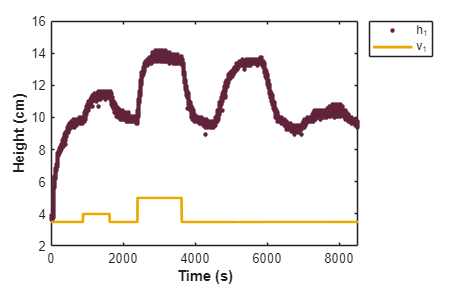

% eTape 1 & Pump 1
h1 = data.steps.get("eTape1").Values.Data;
v1 = data.steps.get("v1").Values.Data;
step_value1 = 4;

figure(1);
plot(time, h1, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(time, v1, "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_1", "v_1", "Location", "bestoutside")
xlim([0 time(end)])
hold off

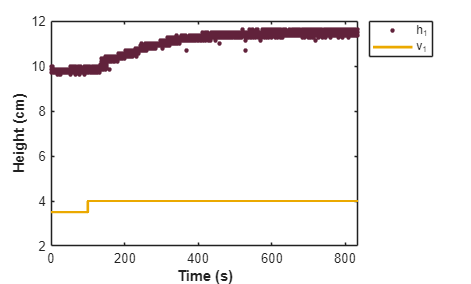


v1_idx = find(v1 == step_value1, 1, "first");
v1_dead = find(v1(1:v1_idx) == 3.5, 1, "last") - 1000;
v1_end = find(v1 == step_value1, 1, "last");
t1 = time(v1_dead:v1_end) - time(v1_dead);

figure(2);
plot(t1, h1(v1_dead:v1_end), "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t1, v1(v1_dead:v1_end), "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_1", "v_1", "Location", "bestoutside")
xlim([0 t1(end)])
% yline(h1_63)
% yline(h1_28)
hold off

% Process Reaction Curve 1
delta1 = h1(v1_end) - h1(v1_dead); % Δ
step1 = v1(v1_end) - v1(v1_dead); % δ
h1_28 = 0.28*delta1 + h1(v1_dead);
h1_63 = 0.63*delta1 + h1(v1_dead);
% t1_28 = t1(find(abs(h1(v1_idx:v1_end) - h1_28) < 0.1, 1, "first"));
% t1_63 = t1(find(abs(h1(v1_idx:v1_end) - h1_63) < 0.1, 1, "first"));
t1_idx = time(v1_idx:v1_end) - time(v1_idx);
h1_idx = h1(v1_idx:v1_end);


idx_28_all_1 = find(abs(h1(v1_idx:v1_end) - h1_28) < 0.1);
idx_63_all_1 = find(abs(h1(v1_idx:v1_end) - h1_63) < 0.1);

% Select the middle index
idx_28_middle_1 = idx_28_all_1(ceil(length(idx_28_all_1)/2));
idx_63_middle_1 = idx_63_all_1(ceil(length(idx_63_all_1)/2));
t1_28 = t1_idx(idx_28_middle_1);
t1_63 = t1_idx(idx_63_middle_1);

% t1_28_interp = interp1(h1(v1_idx:v1_end), time(v1_idx:v1_end), h1_28, 'linear', 'extrap');
% t1_63_interp = interp1(h1(v1_idx:v1_end), time(v1_idx:v1_end), h1_63, 'linear', 'extrap');


% [h1_unique, t1_unique] = unique(h1_idx, "stable", "first");
% t1_28 = interp1(h1_unique, t1_unique, h1_28, "linear");
% t1_63 = interp1(h1_unique, t1_unique, h1_63, "linear");
% plot(t1_unique, h1_unique)
% yline(h1_28)
% yline(h1_63)

% parameters
K1 = delta1/step1;
tau1 = 1.5*(t1_63 - t1_28);
theta1 = t1_63 - tau1;

% transfer function
t1_plot = time(v1_idx:v1_end) - time(v1_idx);
s1 = tf("s");
G1 = (K1*exp(-theta1*s1))/(tau1*s1 + 1)


G1 =
 
                   3.738
  exp(-1.7*s) * -----------
                172.8 s + 1
 
Continuous-time transfer function.


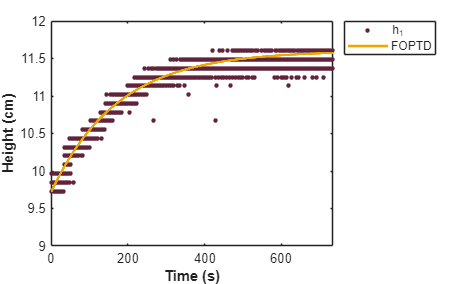

opt1 = RespConfig;
opt1.Amplitude = step1;
t1_G = linspace(0, t1_idx(end), length(t1_idx));
y1 = step(G1, t1_G, opt1)  + h1(v1_dead);

% plot transfer function
figure(3);
plot(t1_idx, h1_idx, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t1_G, y1, "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_1", "FOPTD", "Location", "bestoutside")
ylim([9 12])
xlim([0 t1_idx(end)])
hold off

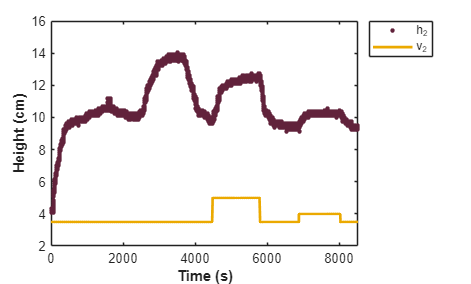

% eTape 2 & Pump 2
h2 = data.steps.get("eTape2").Values.Data;
v2 = data.steps.get("v2").Values.Data;
step_value2 = 5;

figure(4);
plot(time, h2, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(time, v2, "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_2", "v_2", "Location", "bestoutside")
xlim([0 time(end)])
hold off

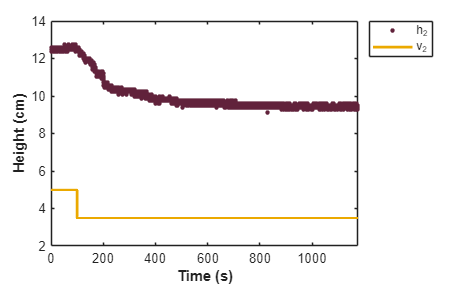


v2_idx = find(v2 == step_value2, 1, "last");
v2_dead = v2_idx - 1000;
v2_end = find(v2 == 4, 1, "first") - 1;
t2 = time(v2_dead:v2_end) - time(v2_dead);

% v2_idx = find(v2 == step_value2, 1, "first");
% v2_dead = find(v2(1:v2_idx) == 3.5, 1, "last") - 1000;
% v2_end = find(v2 == step_value2, 1, "last");
% t2 = time(v2_dead:v2_end) - time(v2_dead);

figure(5);
plot(t2, h2(v2_dead:v2_end), "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t2, v2(v2_dead:v2_end), "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_2", "v_2", "Location", "bestoutside")
xlim([0 t2(end)])
% yline(h2_28)
% yline(h2_63)
% yline(h2(v2_idx))
hold off

% Process Reaction Curve 2

% this one is used
% delta2 = h2(v2_end) - h2(v2_dead); % Δ
% step2 = v2(v2_end) - v2(v2_dead); % δ
% h2_28 = 0.28*delta2 + h2(v2_dead);
% h2_63 = 0.63*delta2 + h2(v2_dead);
% t2_28 = t2(find(abs(h2(v2_idx:v2_end) - h2_28) < 0.1, 1, "last"));
% t2_63 = t2(find(abs(h2(v2_idx:v2_end) - h2_63) < 0.1, 1, "last"));

% mean(h2((find(t2 == 317, 1, "first")):end))

delta2 = h2(v2_end) - h2(v2_dead); % Δ
step2 = v2(v2_end) - v2(v2_dead); % δ
h2_28 = 0.28*delta2 + h2(v2_dead);
h2_63 = 0.63*delta2 + h2(v2_dead);
% t2_28 = t2(find(abs(h2(v2_idx:v2_end) - h2_28) < 0.1, 1, "first"));
% t2_63 = t2(find(abs(h2(v2_idx:v2_end) - h2_63) < 0.1, 1, "first"));

t2_idx = time(v2_idx:v2_end) - time(v2_idx);
h2_idx = h2(v2_idx:v2_end);

idx_28_all_2 = find(abs(h2(v2_idx:v2_end) - h2_28) < 0.5);
idx_63_all_2 = find(abs(h2(v2_idx:v2_end) - h2_63) < 0.5);

% Select the middle index
idx_28_middle_2 = idx_28_all_2(ceil(length(idx_28_all_2)/2));
idx_63_middle_2 = idx_63_all_2(ceil(length(idx_63_all_2)/2));
t2_28 = t2_idx(idx_28_middle_2);
t2_63 = t2_idx(idx_63_middle_2);

% [h2_unique, t2_unique] = unique(h2_idx, "stable", "first");
% t2_28 = interp1(h2_unique, t2_unique, h2_28, "linear");
% t2_63 = interp1(h2_unique, t2_unique, h2_63, "linear");
% plot(t2_unique, h2_unique)
% yline(h2_28)
% yline(h2_63)


% parameters
K2 = delta2/step2;
tau2 = 1.5*(t2_63 - t2_28);
theta2 = t2_63 - tau2;

% transfer function
t2_plot = time(v2_idx:v2_end) - time(v2_idx);
s2 = tf("s");
G2 = (K2*exp(-theta2*s2))/(tau2*s2 + 1)


G2 =
 
                    2.076
  exp(-1.15*s) * -----------
                 178.1 s + 1
 
Continuous-time transfer function.


opt2 = RespConfig;
opt2.Amplitude = step2;
t2_G = linspace(0, t2_idx(end), length(t2_idx));
y2 = step(G2, t2_G, opt2) + h2(v2_dead);

% MAPE
MAPE_1 = mape(y1, h1_idx)

MAPE_1 = 0.6189

MAPE_2 = mape(y2, h2_idx)

MAPE_2 = 0.9874

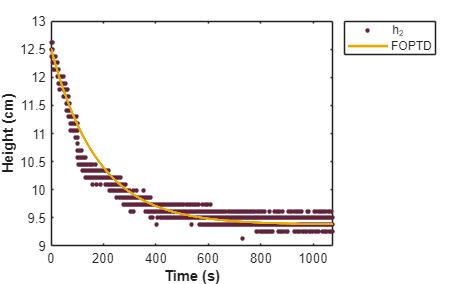


% plot transfer function
figure(6);
plot(t2_idx, h2_idx, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t2_G, y2, "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_2", "FOPTD", "Location", "bestoutside")
ylim([9 13])
xlim([0 t2_idx(end)])
hold off

## Residuals

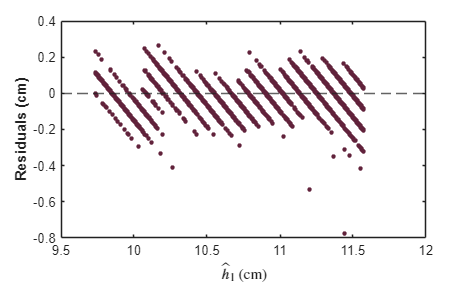

h1_res = h1_idx - y1;
h2_res = h2_idx - y2;

figure(7);
plot(y1, h1_res, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
xlabel({"$\hat{h}_1$ (cm)"}, "Interpreter", "latex", "FontWeight", "bold")
ylabel("Residuals (cm)", "FontWeight", "bold")
yline(0, "--")
hold off

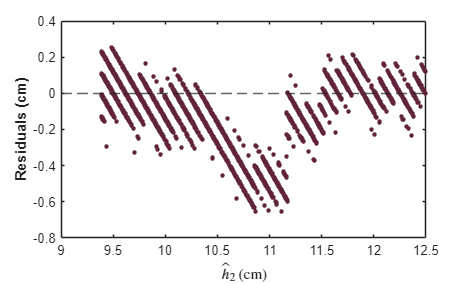


figure(8);
plot(y2, h2_res, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
xlabel({"$\hat{h}_2$ (cm)"}, "Interpreter", "latex", "FontWeight", "bold")
ylabel("Residuals (cm)", "FontWeight", "bold")
yline(0, "--")
hold off

## P Tuning Parameters

% Tank 1
Kc1_P = tau1/(K1*theta1)

Kc1_P = 27.1927


% Tank 2
Kc2_P = tau2/(K2*theta2)

Kc2_P = 74.5937

## PI Tuning Parameters

% Tank 1
Kc1_PI = (0.586/K1)*(theta1/tau1)^-0.916

Kc1_PI = 10.8082

KI1_PI = ((1.03/tau1)*(theta1/tau1)^-0.165)

KI1_PI = 0.0128


% Tank 2
Kc2_PI = (0.586/K2)*(theta2/tau2)^-0.916

Kc2_PI = 28.6189

KI2_PI = ((1.03/tau2)*(theta2/tau2)^-0.165)

KI2_PI = 0.0133

## Nonlinear Model

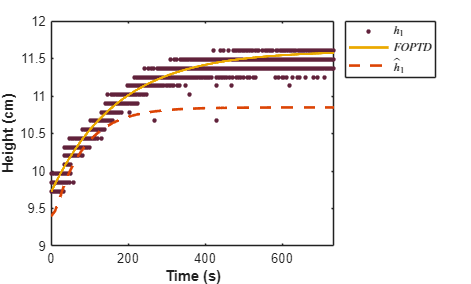

fig1 = openfig("Tank1_NL.fig", "invisible");
axes1 = fig1.Children;  % Get axes
data1 = axes1.Children;  % Get all plotted objects

t1_full_NL = data1.XData';  % Change index to match your nonlinear model line
h1_full_NL = data1.YData';

close(fig1);

t1_idx_start = find(t1_full_NL == 870);
t1_idx_end = find(t1_full_NL == 1630);
t1_NL = t1_full_NL(t1_idx_start:t1_idx_end) - t1_full_NL(t1_idx_start);
h1_NL = h1_full_NL(t1_idx_start:t1_idx_end);

figure(9);
plot(t1_idx, h1_idx, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t1_G, y1, "LineWidth", 2, "Color", "#eba900")
hold on
plot(t1_NL, h1_NL, "LineWidth", 2, "Color", "#dc4405", "LineStyle", "--")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend({"$h_1$", "$FOPTD$" , "$\hat{h}_1$"}, "Interpreter", "latex", "Location", "bestoutside")
ylim([9 12])
xlim([0 t1_idx(end)])
hold off

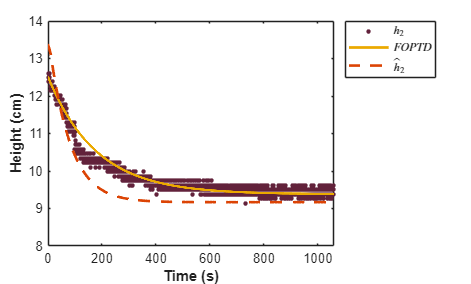

fig2 = openfig("Tank2_NL.fig", "invisible");
axes2 = fig2.Children;  % Get axes
data2 = axes2.Children;  % Get all plotted objects

t2_full_NL = data2.XData';  % Change index to match your nonlinear model line
h2_full_NL = data2.YData';

close(fig2);

t2_idx_start = find(t2_full_NL == 5800);
t2_idx_end = find(t2_full_NL == 6860);
t2_NL = t2_full_NL(t2_idx_start:t2_idx_end) - t2_full_NL(t2_idx_start);
h2_NL = h2_full_NL(t2_idx_start:t2_idx_end);

figure(10);
plot(t2_idx, h2_idx, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#62223b")
hold on
plot(t2_G, y2, "LineWidth", 2, "Color", "#eba900")
hold on
plot(t2_NL, h2_NL, "LineWidth", 2, "Color", "#dc4405", "LineStyle", "--")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend({"$h_2$", "$FOPTD$" , "$\hat{h}_2$"}, "Interpreter", "latex", "Location", "bestoutside")
ylim([8 14])
xlim([0 t2_NL(end)])
hold off

MAPE1_NL = mape(h1_NL, h1_idx(1:length(h1_NL)))

MAPE1_NL = 8.7271

MAPE2_NL = mape(h2_NL, h2_idx(1:length(h2_NL)))

MAPE2_NL = 23.7860